# Introduction: Root Locus

## Example: tuning gain K for a 4th order system

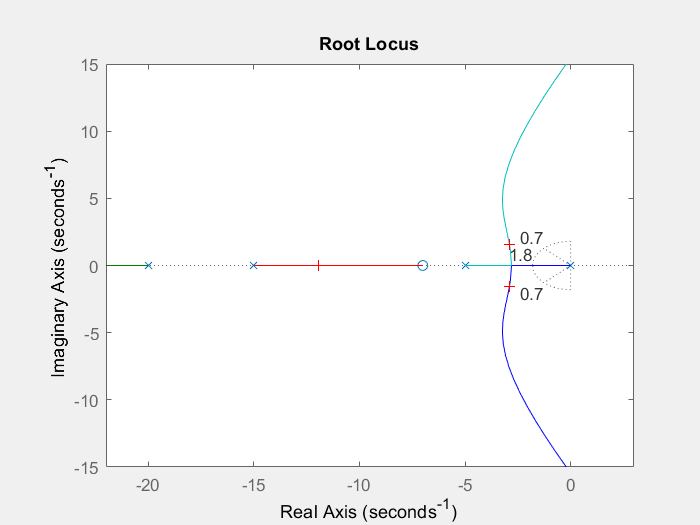

Select a point in the graphics window


selected_point = -2.9422 + 1.5633i

K = 412.3733

root =  -22.2571 + 0.0000i
 -11.9476 + 0.0000i
  -2.8976 + 1.5681i
  -2.8976 - 1.5681i


s = tf('s');
G = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
% draw the rootlocus of G
rlocus(G);
axis([-22 3 -15 15]);

% design criteria
% 1. rise time small than 1 sec
% 2. overshoot less than 5%

% 1. corresponds to wn > 1.8
% 2. corresponds to zeta > 0.7

% draw the criteria on the locus plot
zeta = 0.7;
wn = 1.8;
sgrid(zeta, wn)

% find the gain for the desired root
[K, root] = rlocfind(G)

## Closed Loop Response

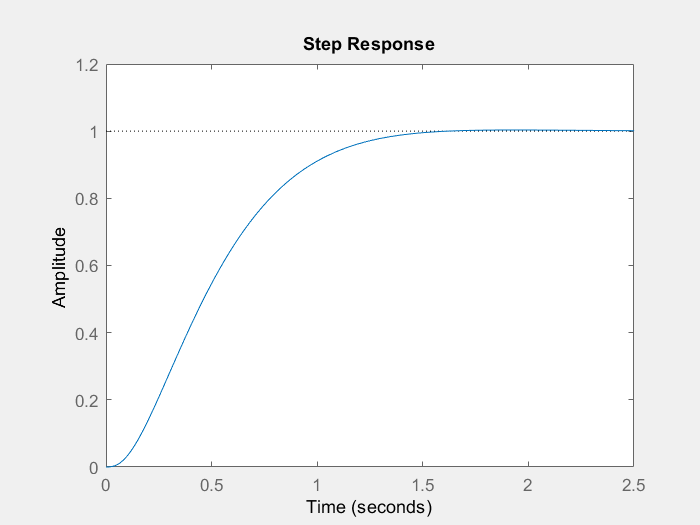

sys_cl = feedback(K*G, 1); % 1 means unit feedback
step(sys_cl)

## Using Control System Designer

controlSystemDesigner(G);